clc
clear
% close all

[FileName, PathName] = uigetfile('.mat');

load([PathName, FileName])

F = Settings.data.F;
if ~iscell(F)
    for i=1:length(F)
        dummy{i} = squeeze(F(:,:,i));
    end
    F = dummy;
end
n = Settings.data.cols;
m = Settings.data.rows;
F = reshape(F, n, m)';



% dummy = cell(200);
% dummy(1:m,1:n) = F;
% F = dummy;
% n = 200;
% m = 200;

if iscell(Settings.data.phi1rn)
    phi1 = reshape(cell2mat(Settings.data.phi1rn), n, m)';
    PHI = reshape(cell2mat(Settings.data.PHIrn), n, m)';
    phi2 = reshape(cell2mat(Settings.data.phi2rn), n, m)';
else
    phi1 = reshape((Settings.data.phi1rn), n, m)';
    PHI = reshape((Settings.data.PHIrn), n, m)';
    phi2 = reshape((Settings.data.phi2rn), n, m)';
end

% phi1 = reshape((Settings.data.phi1rn), n, m)';
% PHI = reshape((Settings.data.PHIrn), n, m)';
% phi2 = reshape((Settings.data.phi2rn), n, m)';

% phi1 = reshape(Settings.Angles(:,1), n, m)';
% PHI = reshape(Settings.Angles(:,2), n, m)';
% phi2 = reshape(Settings.Angles(:,3), n, m)';

% phi1 = reshape(cell2mat(Settings.data.phi1rn), n, m)';
% PHI = reshape(cell2mat(Settings.data.PHIrn), n, m)';
% phi2 = reshape(cell2mat(Settings.data.phi2rn), n, m)';

% phi1 = reshape(shiftdim(Settings.Angles(:,1)), n, m)';
% PHI = reshape(shiftdim(Settings.Angles(:,2)), n, m)';
% phi2 = reshape(shiftdim(Settings.Angles(:,3)), n, m)';

iqRS = reshape(Settings.IQ, n, m)';

sseRS = reshape((Settings.data.SSE),n,m)';
if iscell(sseRS)
    sseRS = cell2mat(sseRS);
end

eps = zeros(3,3,m,n);
sig = eps;
devsigmat = eps;


if isfield(Settings,'camphi1')
    Qmp = euler2gmat(Settings.camphi1,Settings.camPHI,Settings.camphi2);
    Qmi = [0 -1 0;1 0 0;0 0 1];
    sampletilt = Settings.SampleTilt;
    Qio = [cos(sampletilt) 0 -sin(sampletilt);0 1 0;sin(sampletilt) 0 cos(sampletilt)];
    Qpo = Qio*Qmi*Qmp'*[-1 0 0;0 1 0;0 0 -1];
    
    Qps = Qpo;
    disp('Using camera angles')
else
    alpha=pi/2-Settings.SampleTilt+Settings.CameraElevation;
    Qps=[0 -cos(alpha) -sin(alpha);...
        -1     0            0;...
        0   sin(alpha) -cos(alpha)];
end

gsum = 0;
gcount = 0;
epsnorm = zeros(m,n);
devsignorm = epsnorm;
strainenergy = epsnorm;
for i = 1:m
    for j=1:n
        g = euler2gmat(phi1(i,j),PHI(i,j), phi2(i,j));
        eps(:,:,i,j) = ((Qps'*g'*cell2mat(F(i,j))*g*Qps) - eye(3));%symmpart
%         eps(:,:,i,j) = (g'*(cell2mat(F(i,j)))*g - eye(3));%symmpart
%         sig(:,:,i,j) = ((Qps'*g'*squeeze(Settings.data.sigma(:,:,(i-1)*n + j))*g*Qps) - eye(3));
%         sig(:,:,i,j) = ((g'*squeeze(Settings.data.sigma(:,:,(i-1)*n + j))*g));
        if 1%iqRS(i,j) > 800
            gsum = gsum + g;
            gcount = gcount + 1;
        end
        epsnorm(i,j) = norm(squeeze(eps(:,:,i,j)));
        devsig = squeeze(sig(:,:,i,j));
        p = trace(devsig)/3;
        devsig = devsig - p*eye(3);
        devsigmat(:,:,i,j) = devsig;
        devsignorm(i,j) = norm(devsig);
        strainenergy(i,j) = sum(sum(eps(:,:,i,j).*sig(:,:,i,j)));
    end
end
gsum/gcount

ans =    -0.0937   -0.0186   -0.1976
    0.5219    0.2000    0.0725
    0.1761   -0.1465    0.0056


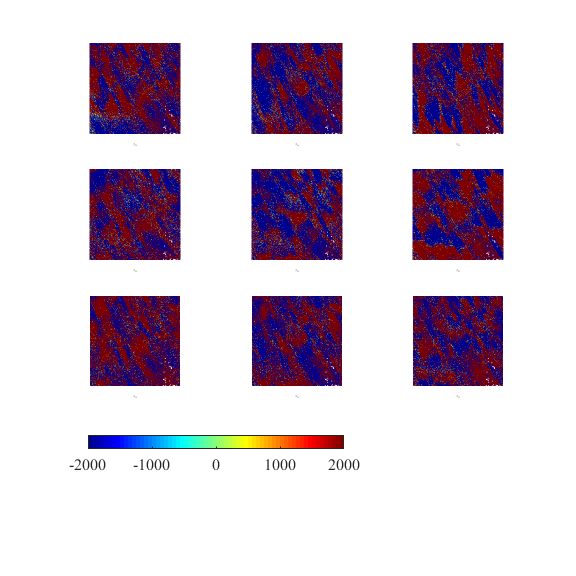


% alphacompplot(eps, ones(m,n), .005, -.005)
% colormap('jet')

% labels = {'$\epsilon_{11}$';'$\epsilon_{12}$';'$\epsilon_{13}$';'$\epsilon_{21}$';'$\epsilon_{22}$';'$\epsilon_{23}$';'$\epsilon_{31}$';'$\epsilon_{32}$';'$\epsilon_{33}$'};
labels = {'$\beta_{11}$';'$\beta_{12}$';'$\beta_{13}$';'$\beta_{21}$';'$\beta_{22}$';'$\beta_{23}$';'$\beta_{31}$';'$\beta_{32}$';'$\beta_{33}$'};
alphacompplotlabels(1e6*eps, (sseRS)>1000, 2000, -2000,labels, 10); colormap('jet')

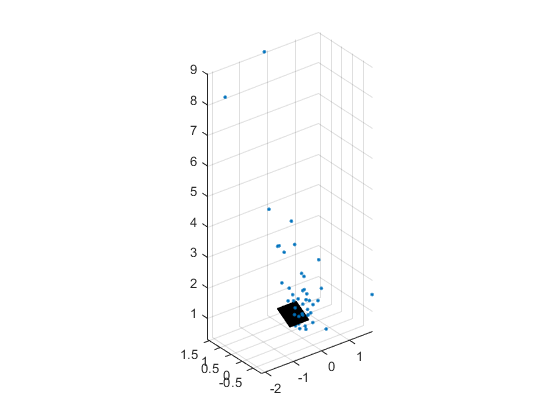


figure; surf(reshape(Settings.XStar,m,n)',reshape(Settings.YStar,m,n)',reshape(Settings.ZStar,m,n)',2*ones(n,m))
axis equal
hold on
plot3(Settings.PCList{2,7}.CalibrationPointsPC(:,1),Settings.PCList{2,7}.CalibrationPointsPC(:,2),Settings.PCList{2,7}.CalibrationPointsPC(:,3),'.')


% labels = {'\epsilon_{11}';'\epsilon_{12}';'\epsilon_{13}';'\epsilon_{22}';'\epsilon_{23}';'\epsilon_{33}'};
% epscompplot(eps, ones(m,n), .0006, -.0006,labels, 12, 2.5e-7)
% colormap('jet')

% figure; imagesc(strainenergy.*(sseRS<10)); axis image; colormap('jet')
% 
% alphacompplot(sig, sseRS>15, 500e6, -500e6)
% colormap('jet')
% 
% figure; imagesc(devsignorm); axis image; colormap('jet')

% figure; imagesc(squeeze(eps(1,2,:,:))); axis image; colormap('jet'); caxis([-.005 .005])

[o,p] = size(phi1); eulerimage = zeros(o,p,3); eulerimage(:,:,1) = phi1/(2*pi); eulerimage(:,:,2) = PHI/pi;eulerimage(:,:,3) = phi2/(2*pi);
% figure; imshow(eulerimage); axis image

% zerp = iqRS;
% zerp(1:5,1:133) = 0;
% figure; imagesc(zerp); axis image

if exist('alpha_data','var')
    figure; imagesc((sseRS<3).*reshape(log10(alpha_data.alpha_total9),n,m)'); axis image; caxis([13 16]); colormap('jet')
    
    Fa = alpha_data.Fa;
    Fc = alpha_data.Fc;
    dummy = {};
    dummi = {};
    if ~iscell(Fa)
        for i=1:length(Fa)
            dummy{i} = squeeze(Fa(:,:,i));
            dummi{i} = squeeze(Fc(:,:,i));
        end
        Fa = dummy;
        Fc = dummi;
    end
    Fa = reshape(Fa, n, m)';
    Fc = reshape(Fc, n, m)';
    for i = 1:m
        for j=1:n
            betA(:,:,i,j) = ((Qps'*cell2mat(Fa(i,j))*Qps) - eye(3));%symmpart
            betC(:,:,i,j) = ((Qps'*cell2mat(Fc(i,j))*Qps) - eye(3));%symmpart

        end
    end
    
    labels = {'$\beta_{11}$';'$\beta_{12}$';'$\beta_{13}$';'$\beta_{21}$';'$\beta_{22}$';'$\beta_{23}$';'$\beta_{31}$';'$\beta_{32}$';'$\beta_{33}$'};
    alphacompplotlabels(1e6*betA/2.92, (sseRS)>1000, 500, -500,labels, 10); colormap('jet')
    alphacompplotlabels(1e6*betC, (sseRS)>1000, 500, -500,labels, 10); colormap('jet')
    
    stepsize = alpha_data.stepsizea;
    betaderiv1 = betA/stepsize;
    betaderiv2 = -betC/stepsize;
    
    alphavecp = CurlBeta(betaderiv1,betaderiv2);

    alphaplot = zeros(3,3,m,n);

    alphaplot(1,3,:,:) = alphavecp(1,:,:);
    alphaplot(2,3,:,:) = alphavecp(2,:,:);
    alphaplot(3,3,:,:) = alphavecp(3,:,:);
    alphaplot(1,2,:,:) = alphavecp(4,:,:);
    alphaplot(2,1,:,:) = alphavecp(5,:,:);
    alphaplot(1,1,:,:) = alphavecp(6,:,:);

    alphacompplot(alphaplot,iqRS<100,2e2,-2e2)
    colormap('jet')
    
    alphacompplot(alphaplot/3.84e-10,iqRS<100,.5e12,-.5e12)
    colormap('jet')
end


% 
% for i = 1:m
%     for j=1:n
%         Ba(:,:,i,j) = ((squeeze(alpha_data.Fa(:,:,(i-1)*n + j))) - eye(3));
%         Bc(:,:,i,j) = ((squeeze(alpha_data.Fc(:,:,(i-1)*n + j))) - eye(3));
%         derpalpha(:,:,i,j) = ((squeeze(alpha_data.alpha(:,:,(i-1)*n + j))));
%         if 1%iqRS(i,j) > 800
%             gsum = gsum + g;
%             gcount = gcount + 1;
%         end
% 
%     end
% end
% 
% alphacompplot(Ba, ones(m,n), .0005, -.0005)
% colormap('jet')
% alphacompplot(Bc, ones(m,n), .0005, -.0005)
% colormap('jet')
% 
% alphacompplot(derpalpha, ones(m,n), 5e12, -5e12)
% colormap('jet')